# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11


## Partie 1

Puissance_demandes = linspace(sum(Pmin),sum(Pmax),10)';
N = 5;
%fonction objectif
Cout_Total = @(x) A'*(x.^2) + B'*x + sum(C); 
% Valeurs de cout et puissances
MPCe = [];
MCo = [];
% contraintes inégalités linéaires
for k = 1:10
    Aineq = -ones(1,N);
    Bineq = -Puissance_demandes(k);


% contraintes égalités linéaires
    Aeq = [];
    Beq = [];  
% Définition des bornes
    lb = Pmin;
    ub = Pmax;
% Solver : fmincon
    x0 = (Pmin + Pmax)/2 ;  % Initialisation
    option=optimoptions('fmincon','display','iter');
% Affichage des résultats
    [x,fval,flag,out]= fmincon(Cout_Total,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',option);
    MPCe = [MPCe x];
    MCo=[MCo fval];
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.837164e+05    0.000e+00    1.533e+03
    1      12    1.183182e+05    0.000e+00    8.219e+02    1.398e+02
    2      18    1.147321e+05    0.000e+00    8.117e+02    3.655e+00
    3      24    1.046825e+05    0.000e+00    7.312e+02    1.065e+01
    4      30    9.696904e+04    0.000e+00    5.544e+02    9.617e+00
    5      36    9.176246e+04    0.000e+00    3.448e+02    1.305e+01
    6      42    8.408938e+04    0.000e+00    1.648e+02    2.803e+01
    7      48    8.406296e+04    0.000e+00    1.299e+01    1.402e-01
    8      54    8.403975e+04    0.000e+00    9.227e-01    1.384e-01
    9      60    8.403794e+04    0.000e+00    1.414e-03    8.741e-03
   10      66    8.403785e+04    0.000e+00    8.917e-05    4.112e-04

Local minimum found that satisfies the cons

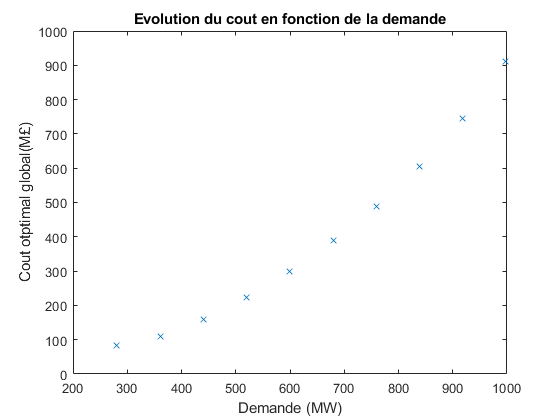

figure
plot(Puissance_demandes,MCo*1e-3,'X')
xlabel('Demande (MW)')
ylabel('Cout otptimal global(M£)')
title('Evolution du cout en fonction de la demande')

Commentaire :

On onbserve une évolution croissante. Ce qui signifie que plus la demande augmente plus le cout de production augmente aussi et cela est tout fait justifiable

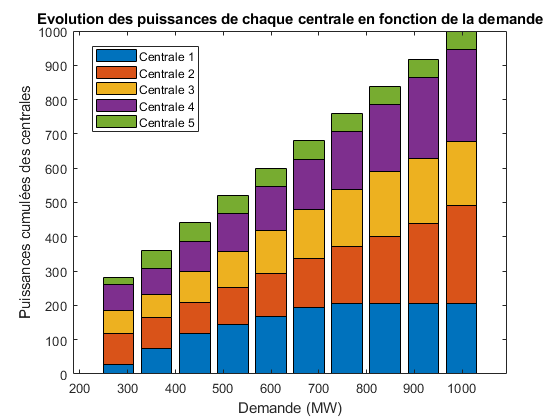

figure
bar(Puissance_demandes,MPCe,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution des puissances de chaque centrale en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

On peut s'apercevoir que certaines centrales sont plus sollicités que d'autres. Autrement dit le dispatcher s'apprivisionne plus chez certains fournisseurs. Cela assez cohérent puisque chacune des centrales ne possédent pas les mêmes quantités minimales et maximales de production. De ce fait, celles qui produisent plus donnent beaucoup en fonction de la deamnde

## Partie 2

%fonction objectif
Quan_Poll = @(x) D'*(x.^2) + E'*x + sum(F); 
% contraintes inégalités linéaires
Aineq = -ones(1,N);
Bineq = -400;
% contraintes égalités linéaires
Aeq = [];
Beq = [];  
% Définition des bornes
lb = Pmin;
ub = Pmax;
% Solver : fmincon
    x0 = (Pmin + Pmax)/2 ;  % Initialisation
    option=optimoptions('fmincon','display','iter');
% Affichage des résultats
    [x1,fval,flag,out]= fmincon(Quan_Poll,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',option);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.778943e+05    0.000e+00    1.424e+03
    1      12    1.227375e+05    0.000e+00    9.119e+02    9.497e+01
    2      18    9.625137e+04    0.000e+00    7.824e+02    3.638e+01
    3      24    9.605571e+04    0.000e+00    7.771e+02    2.244e-01
    4      30    9.370505e+04    0.000e+00    7.241e+02    5.296e+00
    5      36    8.970016e+04    0.000e+00    5.535e+02    1.014e+01
    6      42    8.967597e+04    0.000e+00    4.650e+02    5.499e-02
    7      48    8.755390e+04    0.000e+00    3.084e+02    5.783e+00
    8      54    8.728614e+04    0.000e+00    1.298e+02    4.813e+00
    9      60    8.709043e+04    0.000e+00    1.716e+00    8.619e+00
   10      66    8.708947e+04    0.000e+00    5.342e-01    8.559e-01
   11      72    8.708940e+04    0.000e+00    1.218e-03    2.153e-01
   12      78    8.708940e+04    0.000e+00    6

    [x2,fval2,flag2,out2]= fmincon(Cout_Total,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',option);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.837164e+05    0.000e+00    1.533e+03
    1      12    1.510614e+05    0.000e+00    9.376e+02    1.171e+02
    2      18    1.502212e+05    0.000e+00    9.088e+02    6.744e-01
    3      24    1.384805e+05    0.000e+00    7.936e+02    2.484e+01
    4      30    1.327717e+05    0.000e+00    5.340e+02    1.952e+01
    5      36    1.327438e+05    0.000e+00    4.264e+02    1.432e-01
    6      42    1.318257e+05    0.000e+00    2.290e+02    7.312e+00
    7      48    1.314881e+05    0.000e+00    6.594e+01    7.834e+00
    8      54    1.314657e+05    0.000e+00    1.020e+01    1.315e+00
    9      60    1.314550e+05    0.000e+00    1.140e-01    1.732e+00
   10      66    1.314550e+05    0.000e+00    7.827e-03    1.384e-02
   11      72    1.314550e+05    0.000e+00    1.531e-04    6.663e-04



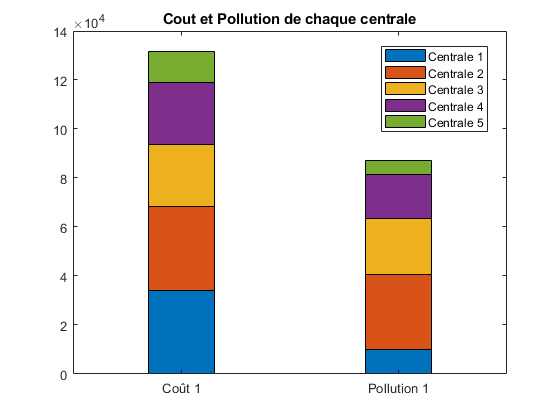

% Valeurs des couts et de la pollution par centrale 
Co= [];
Pol = [];
for k = 1:5
    Cout1= A(k)*((x2(k)).^2) + B(k)*x2(k) + C(k); 
    Poll = D(k)*((x1(k)).^2) + E(k)*x1(k) + F(k); 
    Co = [Co Cout1];
    Pol = [Pol Poll];
end
% exemple 2 (valeurs numériques aléatoires choisies)
x = categorical([{'Coût 1'}, {'Pollution 1'}]);
P = Co;
Q = Pol;
C1=1e5; Pol1=8e4; C2=1.5e5; Pol2=7e4;
bar(x,[P;Q],0.3,'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf(['Cout et Pollution de chaque centrale']))

Selon le diagramme ci dessus les coutes pour chaque sont nettement élévés par rapport à la quantité de pollution. Ce qui est raisonnable.  Une autre évidence celui qui produit plus pollue plus.

## Partie 3

### Méthode de Pondération

taxe = 0.45;
w = linspace(0.1,1, 10);
Cot=[];
Pollu =[];
Cout_Total = @(x) A'*(x.^2) + B'*x + sum(C);
Quan_Poll = @(x) D'*(x.^2) + E'*x + sum(F); 
% F_multi =@(x) (1-w1)*(A'*(x.^2) + B'*x + sum(C)) + w1*(D'*(x.^2) + E'*x + sum(F));
for k = 1:10
    F_multi = @(x) (1-w(k))*(A'*(x.^2) + B'*x + sum(C)) + taxe*w(k)*(D'*(x.^2) + E'*x + sum(F));
    
% contraintes inégalités linéaires
    Aineq = -ones(1,N);
    Bineq = -400;
% contraintes égalités linéaires
    Aeq = [];
    Beq = [];  
% Définition des bornes
    lb = Pmin;
    ub = Pmax;
% Solver : fmincon
    x0 = (Pmin + Pmax)/2 ;  % Initialisation
    option=optimoptions('fmincon','display','iter');
% Affichage des résultats
    [x,fval,flag,out]= fmincon(F_multi,x0,Aineq,Bineq,Aeq,Beq,lb,ub,'',option);
    Cot = [Cot Cout_Total(x)];
    Pollu=[Pollu Quan_Poll(x)];
 end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.578500e+05    0.000e+00    1.443e+03
    1      12    1.408304e+05    0.000e+00    8.781e+02    1.170e+02
    2      18    1.400329e+05    0.000e+00    8.545e+02    6.872e-01
    3      24    1.309501e+05    0.000e+00    7.606e+02    2.000e+01
    4      30    1.237511e+05    0.000e+00    6.111e+02    3.226e+01
    5      36    1.237109e+05    0.000e+00    6.074e+02    1.779e-01
    6      42    1.230721e+05    0.000e+00    2.112e+02    5.768e+00
    7      48    1.229455e+05    0.000e+00    5.533e+01    1.870e+00
    8      54    1.226282e+05    0.000e+00    2.032e+01    9.695e+00
    9      60    1.226255e+05    0.000e+00    1.154e+00    8.942e-01
   10      66    1.226252e+05    0.000e+00    1.147e-02    1.673e-01
   11      72    1.226252e+05    0.000e+00    5.804e-04    2.088e-03



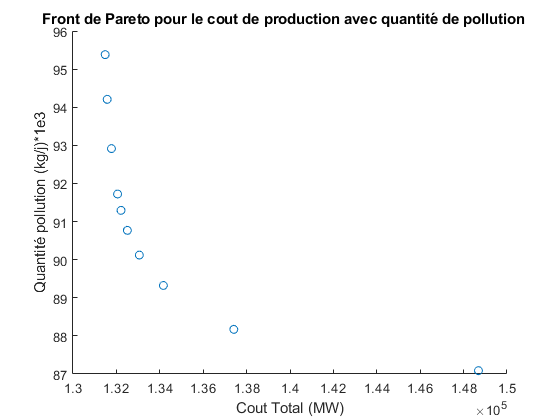

% exemple 3 (valeurs numériques aléatoires choisies)
X=Cot;
Y=Pollu*1e-3;
scatter(X,Y)
% colormap winter
% c = colorbar;
% c.Label.String = 'Niveau de bl bla bla';
xlabel('Cout Total (MW)')
ylabel('Quantité pollution (kg/j)*1e3')
title(' Front de Pareto pour le cout de production avec quantité de pollution ')

Pour une pondération qui varie d'un pas de 0.1 la solution varie énormement. Ici le point du nuages qui minise le tout est le point 5 (w=0.5). Finalement on se rend compte que lorsque la pondération est équilibré on a une minisation des deux cotés. 

## Méthodes des espsilon contraintes

% fun = @(x) A'*(x.^2) + B'*x + sum(C);
% %  contraintes inégalités linéaires
% Aineq = -ones(1,N);
% Bineq = -400;
% % contraintes égalités linéaires
% Aeq = [];
% Beq = [];  
% % Définition des bornes
% lb = Pmin;
% ub = Pmax;
% % Solver : fmincon
% x0 = (Pmin + Pmax)/2 ;  % Initialisation
% option=optimoptions('fmincon','display','iter');
% % Affichage des résultats
% [x,fval,flag,out]= fmincon(fun,x0,Aineq,Bineq,Aeq,Beq,lb,ub,nonlcont,option);

### Fonction contrainte non linéaire

% function [c,ceq]=nonlcont(x)
% eps = 90000;
% f2 = D'*(x.^2) + E'*x + sum(F);
% c(1) = D'*(x.^2) + E'*x + sum(F);
% 
% ceq = [];
% end

Pour cette partie, le code a généré une erreur que j'ai pas comprise.

## Conclusions

On peut conclure que l'optimum dépend grandament des paramètres que nous choissisons. Lorsqu'il sagit de de choix multiobjectif, il est difficile de trouver un compromis parfait.  